# ***Trasmissione CDMA e Inteferenza dovuta al Jamming ***

## ***Intro***

Obiettivo del progetto è simulare una comunicazione multi utente utilizzando la tecnica di accesso CDMA-DSSS (Code Division Multiple Access - Direct Sequence Spread-Spectrum). In particolare, si analizza il segnale in fase di modulazione, trasmissione su canale AWGN e demodulazione evidenziando le modifiche intervenute per effetto dello spreading. Ulteriore analisi si riferisce all'effetto di un segnale di Jamming insistente sul canale con particolare riferimento a tre differenti tipologie di Jammer ovvero Broadband, Single Tone e Multi-Tone, analizzando il disturbo anche in termini di potenze.

Sono riportati i grafici relativi all'andamento del BER (Bit Error Rate) in funzione di alcuni parametri fondamentali del sistema quali:

- Processing Gain (Lc)

- Numero di utenti in trasmissione

- Qualità del canale 

- Tipologia di Jamming

- Intensità del Jammer

Infine, si presenta un esempio di trasmissione di clip audio in condizioni normali di funzionamento e sotto l'effetto del Jammer. 

## **Trasmissione CDMA**

La tecnica di accesso multiplo a divisione di codice CDMA è caratterizzata dal fatto che ogni trasmettitore codifica l’informazione in modo diverso dagli altri. Le tecniche spread spectrum sono nate in ambiente militare alla fine degli anni ’40 e successivamente introdotte anche in ambiente civile. L’idea di base è quella di trasformare un segnale *s(t)*, moltiplicandolo per una parola codice *c(t)*, in un segnale “like-noise” avente larghezza di banda molto maggiore di quella originale. In demodulazione, il segnale viene moltiplicato (despreading) nuovamente per la stessa parola codice *c(t)* e l’effetto è quello di ottenere al ricevitore il segnale precedente all’operazione di spreading. Si vedano le immagini sotto riportate per una comprensione d'insieme.

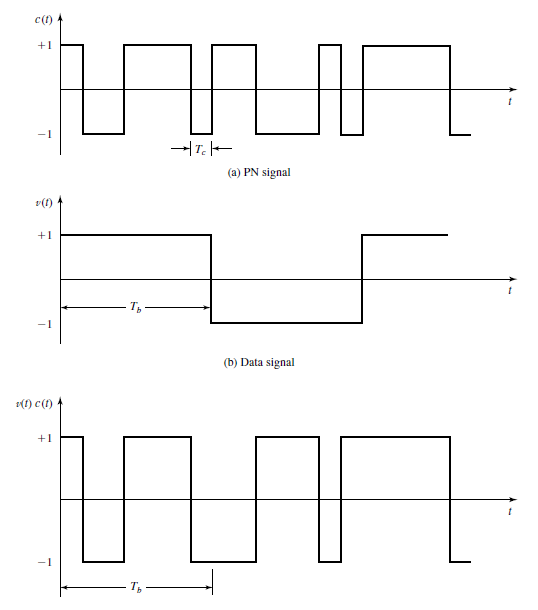      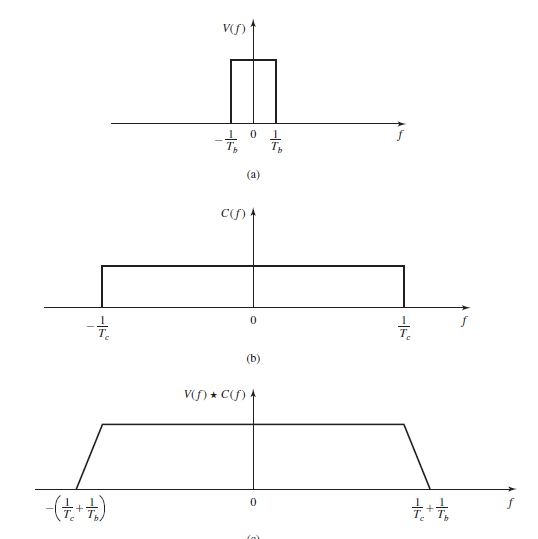

## **Pseudo-random noise Code (PN Code)**

Un PN Code utilizzato nelle comunicazioni CDMA consiste in *n* unità chiamate *chips* che possono assumere due valori [-1, 1] polare o [0,1]. La combinazione di ogni simbolo con un PN Code completo corrisponde ad un DS Processing-Gains di lunghezza uguale alla parola codice. Affinchè un PN Code sia utilizzabile in una comunicazione DSSS, deve soddisfare i seguenti requisiti:

- La sequenza deve essere costituita da due valori

- Il codice deve avere una alta auto-correlazione in modo da essere identificato

- Il codice deve avere una bassa cross-correlazione in modo da consentire la presenza di più utenti nel sistema

- Il codice deve essere bilanciato ovvero la differenza tra 1 e 0 nel codice deve essere minima che implica una buona densità spettrale (distribuire equamente l'energia del segnale sull'intera banda di frequenze)

Si distinguono due tipologie di codici:

- Codici ortogonali: Walsh Sequences

- Codici non-ortogonali (Shift Register Sequences): M-Sequences, i Gold Codes e i Kasami Codes

Ai fini della simulazione vengono utilizzati i codici M-Sequences in quanto i Gold Codes e i Kasami Codes sono rielaborazioni. 

### M-Sequences

Linear Feedback Shift Register (LFSR)

## **Trasmissione di un singolo segnale**

In questa sezione, si evidenziano le varie fasi di trasformazione del segnale con grafici sia nel tempo che in frequenza. Si parte da un segnale binario *v(t)* e, per mezzo di una modulazione BPSK, lo si riporta sui valori [-1, 1]. Il segnale modulato viene moltiplicato per una parola codice *c(t), *ottenendo il segnale *spreaded*. Tale segnale viene combinato con i segnali relativi agli altri utenti, per poi essere trasmesso su di un canale AWGN. All'uscita del canale, il segnale trasmesso *y(t)* viene rimoltiplicato per la stessa parola codice *c(t)*, ottenendo il segnale *despreaded*. Il segnale ottenuto viene quindi integrato e demodulato per ottenere il segnale originario. Osserviamo come nel dominio della frequenza il segnale *spreaded* occupa all'incirca la stessa banda di frequenze della parola codice *c(t)*. 

Potenza_jamming = 0

Potenza_rumore = 0.3990

Potenza_interferenza = 0.3990

Potenza_segnale = 1

Potenza_despreading = 16.2077

Potenza_interferenza_altri_utenti = 14.8087

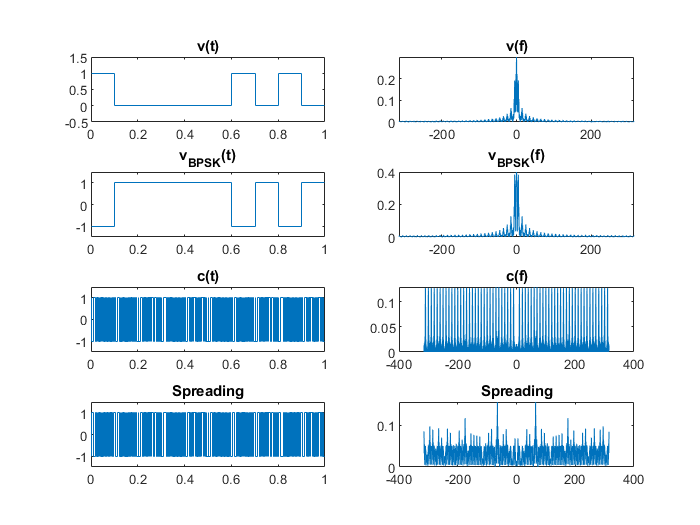

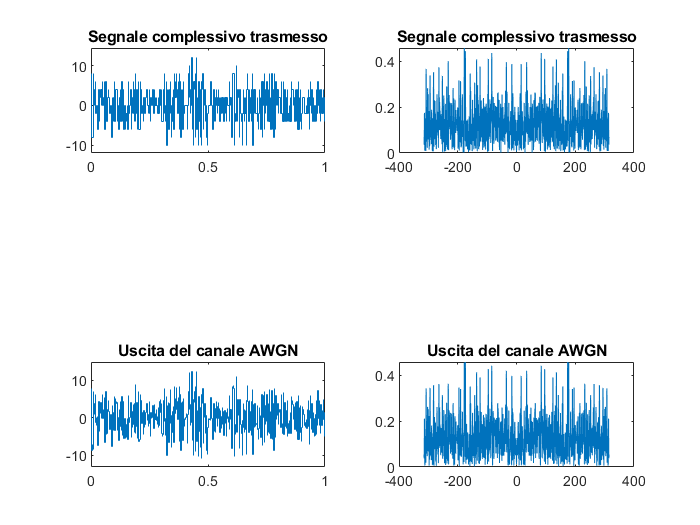

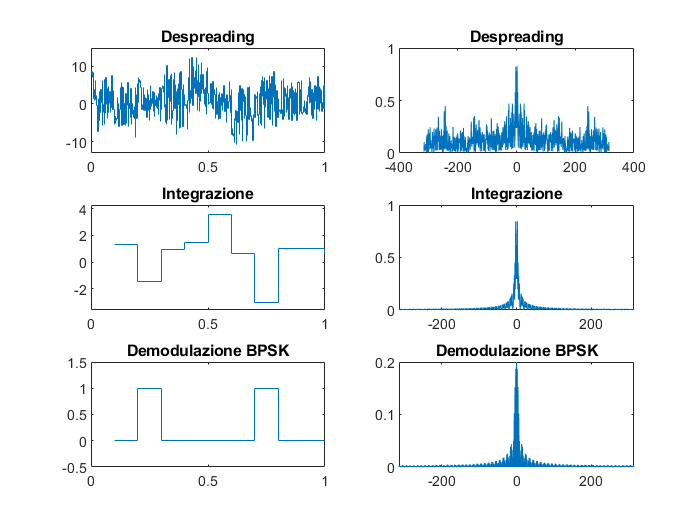

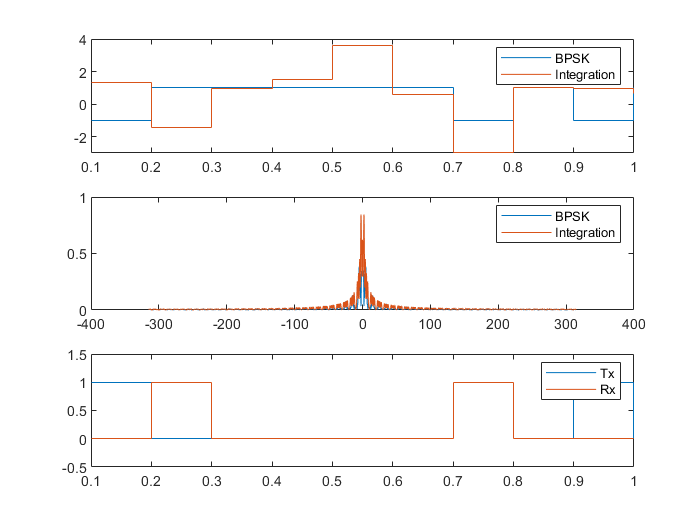

%% Variabili
Lc=63;                     %Processing gain
Tb=1/10;                   %Tempo di bit
len_signal=10;             %Lunghezza dei segnali trasmessi
Nuser = 16;                %Numero di utenti
EbNo = 20;                 %Qualità del canale
plotting = true;           %Plotting nel dominio del tempo e frequenza
jammer_intensity = 0;      %Rapporto potenza jammer/potenza segnale
jamming_type=0;            %Tipo Jammer 0:Broadband 1:SingleTone 2:MultiTone
alpha = 0.5;               %Valori da 1 a 5 -> Figura 10.44

%Matrici dei segnali in forma binaria
v_t_ref = sequence_generator(Nuser,len_signal);

[n_err,ber,rxbits] = cdma_transmission_and_metrics(v_t_ref,Lc,Tb,EbNo,plotting,jammer_intensity,jamming_type,alpha);

ber = 0.2500

f =   Figure (40) with properties:

      Number: 40
        Name: ''
       Color: [1 1 1]
    Position: [1 31.4000 1536 758.4000]
       Units: 'pixels'

  Show all properties


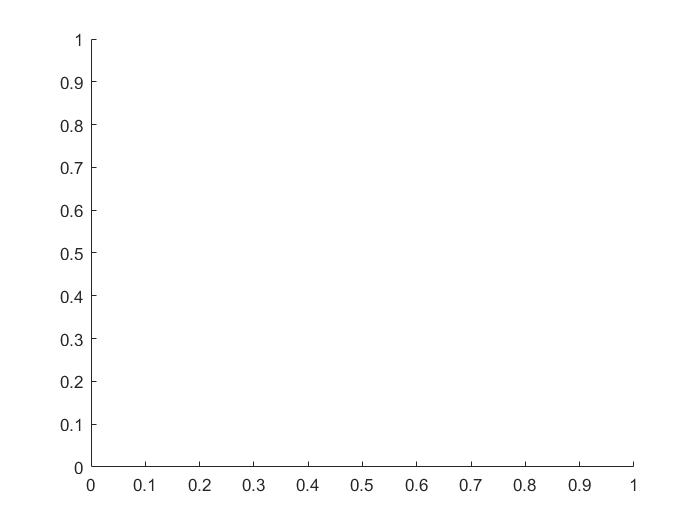

Error using copyobj
Functionality not supported with figures created with the uifigure function. For more information, see Graphics Support in App Designer.

Bit_Error_Rate = mean(ber)

### **Jamming**

Nelle reti wireless, il jamming è definito come l'interferenza nelle comunicazioni esistenti al fine di diminuire il rapporto segnale-rumore al ricevitore attraverso la trasmissione di segnali interferenti trasmettendo tipicamente sulla stessa frequenza e con la stessa modulazione del segnale che si vuole disturbare.  

Il dispositivo che causa tale disturbo è detto *Jammer* e la sua efficacia dipende da vari fattori che contribuiscono alla classificazione del dispositivo e della tipologia di Jamming. In seguito, verranno trattate le seguenti categorie di segnali di Jamming:

- Broadband

- Single-Tone

- Multi-Tone

            

Un single-tone Jammer trasmette una segnale non modulato con potenza J nella banda del segnale *spreaded*. Il massimo effetto di disturbo si ottiene se il tono è posto su una delle frequenze centrali della sottoportante. Possiamo anche introdurre jamming con un numero multiplo (KJ) di toni.

### **Trasmissione di un singolo segnale con Jamming**

Potenza_jamming = 15.1838

Potenza_rumore = 0.4990

Potenza_interferenza = 15.6827

Potenza_segnale = 1

Potenza_despreading = 20.7059

Potenza_interferenza_altri_utenti = 4.0231

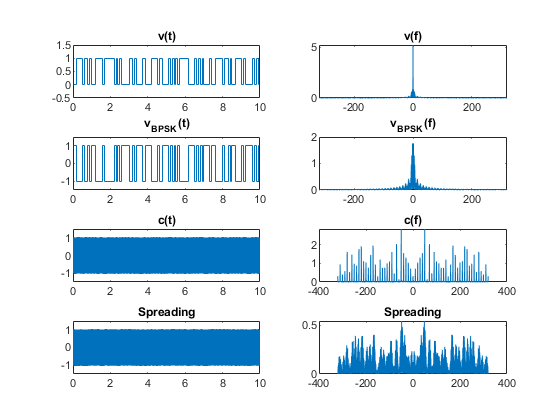

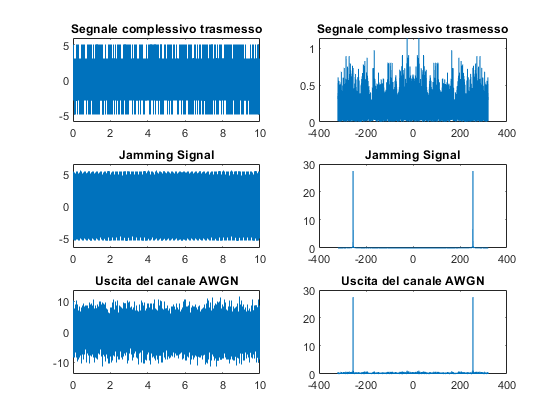

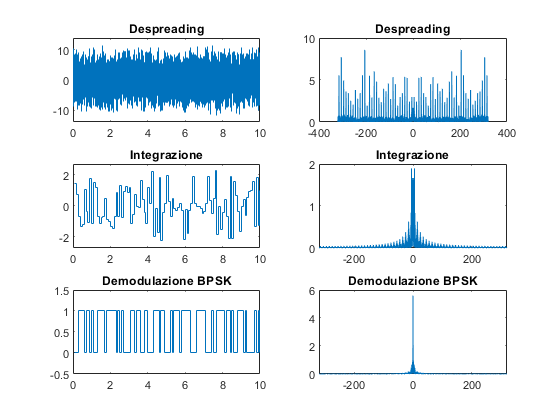

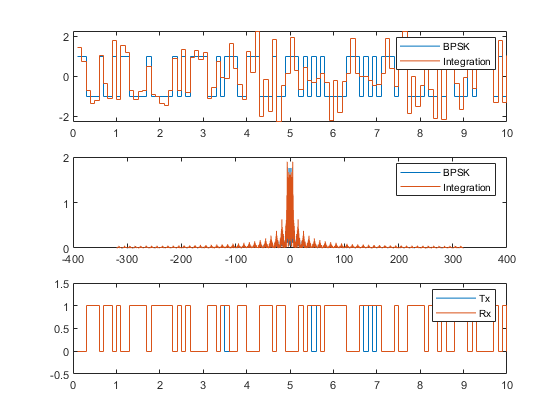

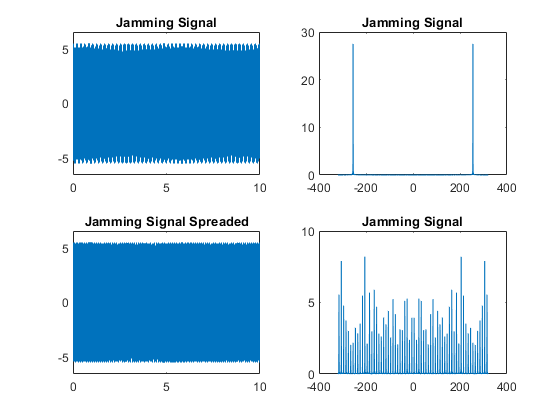

%% Variabili
Lc=63;                     %Processing gain

Tb=1/10;                   %Tempo di bit

Bit_Error_Rate = 0.0400

len_signal=10;             %Lunghezza dei segnali trasmessi
Nuser = 16;                %Numero di utenti
EbNo = 20;                 %Qualità del canale
plotting = true;           %Plotting nel dominio del tempo e frequenza
jammer_intensity = 2;      %Rapporto potenza jammer/potenza segnale
jamming_type=2;            %Tipo Jammer 0:Broadband 1:SingleTone 2:MultiTone
alpha = 0.5;               %Valori da 1 a 5 -> Figura 10.44

%Matrici dei segnali in forma binaria
v_t_ref = sequence_generator(Nuser,len_signal);

[n_err,ber,rxbits] = cdma_transmission_and_metrics(v_t_ref,Lc,Tb,EbNo,plotting,jammer_intensity,jamming_type,alpha);
ber = mean(ber)
Bit_Error_Rate = mean(ber)

### BER al variare di Lc e Nutenti (Senza Jamming)

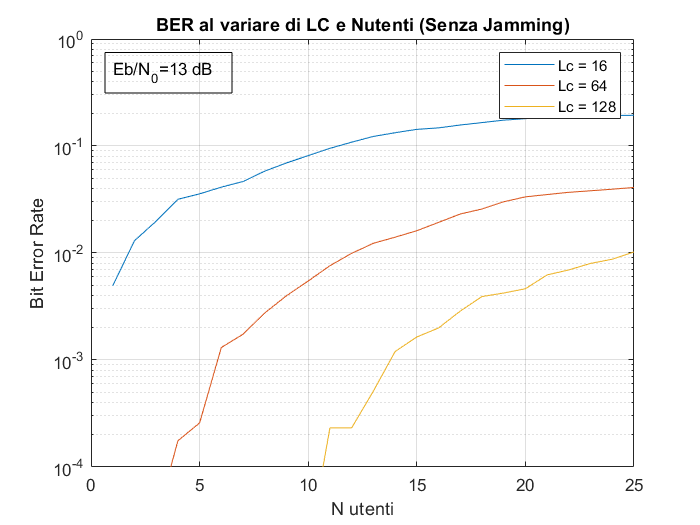

%% Variabili
Lc_values = [15 63 127 511];    %Processing gain
Tb=1/50;                        %Tempo di bit
len_signal=1000;                %Lunghezza dei segnali trasmessi
Nuser = 55;                     %Numero di utenti
EbNo = 20;   
mean_ber = zeros(length(Lc_values),Nuser);	%Nuser rappresenta il numero massimo di utenti da considerare
LegendsStrings = cell(length(Lc_values),1);

for i=1:length(Lc_values)
    for k = 1:Nuser
        bers = zeros(1,10);
        for j=1:length(bers)
            v_t_ref = sequence_generator(k,len_signal);
            [n_err,ber,rxbits] = cdma_transmission_and_metrics(v_t_ref,Lc_values(i),Tb,EbNo,0,0,0,0);
            bers(j) = mean(ber);
        end
        mean_ber(i,k) = mean(bers);
    end

    LegendsStrings{i} = ['Lc = ',num2str(Lc_values(i))];
end

mean_ber(mean_ber==0)=10^-9;  %Approssimazione ai fini di rappresentazione

figure
semilogy(1:Nuser, mean_ber(1,:))
hold on
for k =2:length(Lc_values)
    semilogy(1:Nuser,mean_ber(k,:))
end

grid
xlabel('Numero utenti')
ylabel('Bit Error Rate')
ylim([10^-4 1])
legend(LegendsStrings, 'Interpreter', 'none')
dim = [.15 .9 .0 .0];
str = join(['Eb/N_0=',num2str(round(db(EbNo,'power'))),' dB']);
annotation('textbox',dim,'String',str,'FitBoxToText','on');
title('BER al variare di LC e Numero di utenti (Senza Jamming)')

### BER al variare di EbN0 e Nutenti (Senza Jamming)

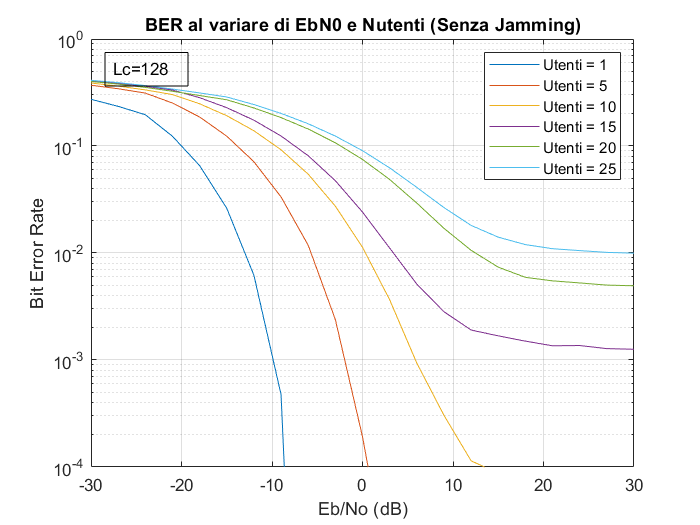

%% Variabili
Lc=127;                     %Processing gain
Tb=1/10;                    %Tempo di bit
len_signal=1000;            %Lunghezza dei segnali trasmessi
EbNos = logspace(-3,3,21);   
Nut = [1 5:5:25];           %Numero di utenti da considerare
mean_ber = zeros(length(Nut),length(EbNos));
LegendsStrings = cell(length(Nut),1);

for i=1:length(Nut)
    for k = 1:length(EbNos)
        v_t_ref = sequence_generator(Nut(i),len_signal);
        bers = zeros(1,10);
        for j=1:length(bers)
            [n_err,ber,rxbits] = cdma_transmission_and_metrics(v_t_ref,Lc,Tb,EbNos(k),0,0,0,0);
            bers(j) = mean(ber);
        end
        mean_ber(i,k) = mean(bers);
    end

    LegendsStrings{i} = ['Utenti = ',num2str(Nut(i))];
end

mean_ber(mean_ber==0)=10^-9; %Approssimazione ai fini di rappresentazione

figure
semilogy(db(EbNos, 'power'), mean_ber(1,:))
hold on
for k =2:length(Nut)
    semilogy(db(EbNos, 'power'),mean_ber(k,:))
end

grid
xlabel('Eb/No (dB)')
ylabel('Bit Error Rate')
ylim([10^-4 1])
legend(LegendsStrings, 'Interpreter', 'none')
dim = [.15 .9 .0 .0];
str = join(['Lc=',num2str(Lc)]);
annotation('textbox',dim,'String',str,'FitBoxToText','on');
title('BER al variare di EbN0 e Numero di utenti (Senza Jamming)')

### Fissiamo il numero di utenti e facciamo variare Lc e EbN0

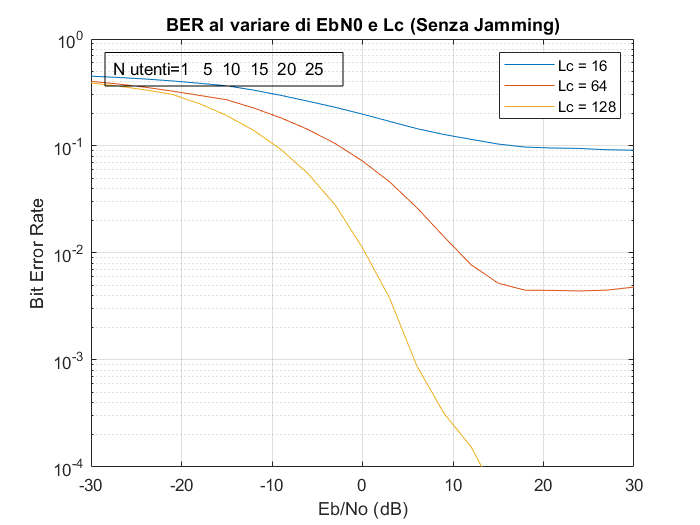

%% Variabili
Lc_values = [63 127 255 511];    %Processing gain
Tb=1/10;                    %Tempo di bit
len_signal=100;            %Lunghezza dei segnali trasmessi
Nuser = 16;                 %Numero di utenti
EbNos = logspace(-3,3,21);	%Intervallo di canali da testare

mean_ber = zeros(length(Lc_values),length(EbNos));
LegendsStrings = cell(length(Lc_values),1);

for i=1:length(Lc_values)
    for k = 1:length(EbNos)
        v_t_ref = sequence_generator(Nuser,len_signal);
        bers = zeros(1,5);
        for j=1:length(bers)
            [n_err,ber,rxbits] = cdma_transmission_and_metrics(v_t_ref,Lc_values(i),Tb,EbNos(k),0,0,0,0);
            bers(j) = mean(ber);
        end
        mean_ber(i,k) = mean(bers);

    end
    LegendsStrings{i} = ['Lc = ',num2str(Lc_values(i))];
end

mean_ber(mean_ber==0)=10^-9; %Approssimazione ai fini di rappresentazione

figure
semilogy(db(EbNos, 'power'), mean_ber(1,:))
hold on
for k =2:length(Lc_values)
    semilogy(db(EbNos, 'power'),mean_ber(k,:))
end

grid
xlabel('Eb/No (dB)')
ylabel('Bit Error Rate')
ylim([10^-4 1])
legend(LegendsStrings, 'Interpreter', 'none')
dim = [.15 .9 .0 .0];
str = join(['Numero utenti= ',num2str(Nuser)]);
annotation('textbox',dim,'String',str,'FitBoxToText','on');
title('BER al variare di EbN0 e Lc (Senza Jamming)')

### BER al variare di Jamming intensity e type

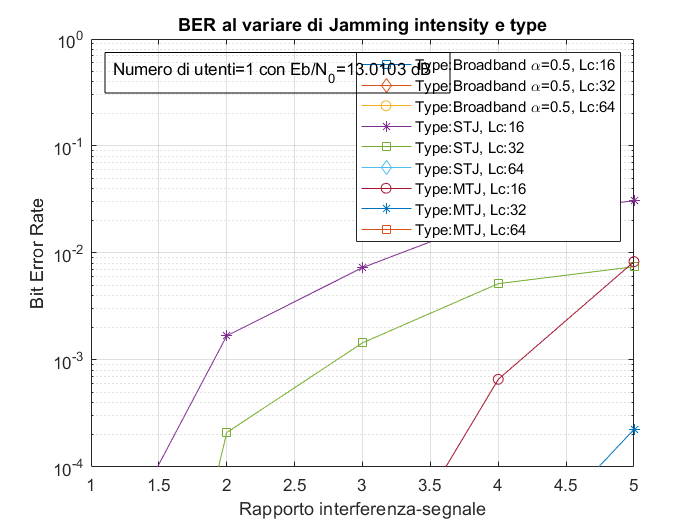

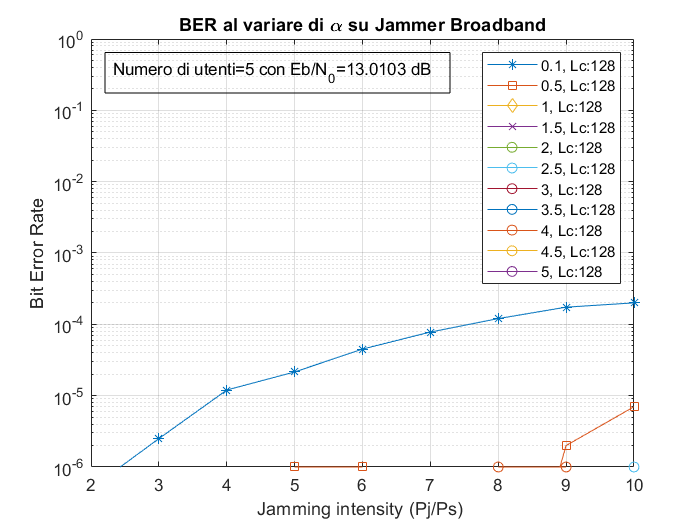

%% Variabili
Lcs=[16 32 64];    %Processing gain
Tb=1/10;           %Tempo di bit
len_signal=1000;   %Lunghezza dei segnali trasmessi
Nuser = 1;         %Numero di utenti
EbNo = 20;   
jam_intensity = [0:1:5];  %Rapporto potenza jammer/potenza segnale
jam_type = [0 1 2];       %Tipo Jammer 0:Broadband 1:SingleTone 2:MultiTone
alpha = 0.5;              %Valori da 1 a 5 -> Figura 10.44

%Matrici dei segnali in forma binaria
v_t_ref = sequence_generator(Nuser,len_signal);

jam_name = {'Broadband \alpha=0.5','STJ','MTJ'};
mean_ber = zeros(length(jam_type)*length(Lcs),length(jam_intensity));
LegendsStrings = cell(length(jam_type)*length(Lcs),1);

for i=1:length(jam_type)
    for z=1:length(Lcs)
        for k = 1:length(jam_intensity)
            bers = zeros(1,100);
            for j=1:length(bers)
                [n_err,ber,rxbits] = cdma_transmission_and_metrics(v_t_ref,Lcs(z),Tb,EbNo,0,jam_intensity(k),jam_type(i),alpha);
                bers(j) = mean(ber);
            end
            mean_ber((i-1)*length(Lcs)+z,k) = mean(bers);
        end
        LegendsStrings{(i-1)*length(Lcs)+z} = ['Type:',jam_name{i},', Lc:',num2str(Lcs(z))];

    end
end

mean_ber(mean_ber==0)=10^-9; %Approssimazione ai fini di rappresentazione

figure
semilogy(jam_intensity, smoothdata(mean_ber(1,:)),'-s')
hold on
for k =2:(length(jam_type)*length(Lcs))
    if mod(k,4)==0
        semilogy(jam_intensity,smoothdata(mean_ber(k,:)),'-*')
    elseif mod(k,4)==1
        semilogy(jam_intensity,smoothdata(mean_ber(k,:)),'-s')
    elseif mod(k,4)==2
        semilogy(jam_intensity,smoothdata(mean_ber(k,:)),'-d')
    else
        semilogy(jam_intensity,smoothdata(mean_ber(k,:)),'-o')
    end
end

grid
title('BER al variare della potenza del Jammer')
xlabel('Rapporto interferenza-segnale')
ylabel('Bit Error Rate')
ylim([10^-4 1])
legend(LegendsStrings, 'Interpreter', 'tex')
dim = [.15 .9 .0 .0];
str = join(['Numero di utenti=',num2str(Nuser),' con Eb/N_0=', num2str(db(EbNo, 'power')), ' dB']);
annotation('textbox',dim,'String',str,'FitBoxToText','on');
title('BER al variare di Jamming intensity e type')

### Trasferimento Audio

% %% Variabili
% Lc=64;                     %Processing gain
% Tb=1/10;                   %Tempo di bit
% EbNo = 20;   
% plotting = true;           %Plotting nel dominio del tempo e frequenza
% jammer_intensity = 5;      %Rapporto potenza jammer/potenza segnale
% jamming_type=0;            %Tipo Jammer 0:Broadband 1:SingleTone 2:MultiTone
% alpha = 2.5;               %Valori da 1 a 5 -> Figura 10.44
% 
% %% Trasferimento Audio
% audio_paths = {'audio/uomo_1.wav', 'audio/uomo_2.wav'};
% 
% [original_audio,v_t_ref,fr_vec] = create_tx_signal(audio_paths);
% [n_err,ber,rxbits] = cdma_transmission_and_metrics(v_t_ref,Lc,Tb,EbNo,plotting,jammer_intensity,jamming_type,alpha);
% [rec_sounds] = retrieve_tx_signals(rxbits, fr_vec, audio_paths);
% [sym_err_dem, sym_dem] = symerr(original_audio,rec_sounds,'row-wise');
% 
% ber
% sym_err_dem